# Evaluation of the models

We have just finished training a model, and as we’ve seen, YOLOv8 allows the use of many different parameters during training. Now, we could train another YOLOv8 model with different parameters. But this raises two important questions: **How can we determine if our current model performs well, or if we need to train a new one? And how can we compare multiple models to decide which one is the best?**

To answer these questions, we rely on **evaluation metrics**. Below, we will explain the most widely used metrics for **object detection.**

### Intersection over Union (IoU) 

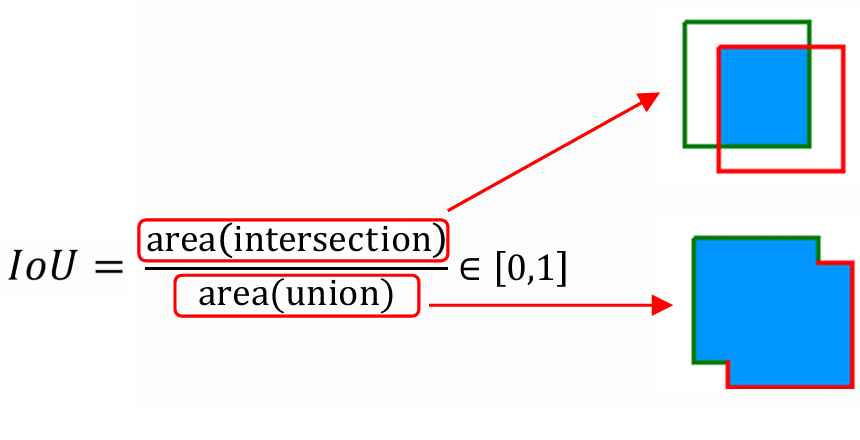

#### Exercise calculate IoU:

function iou = calculateIoU(b1, b2)

    x1 = max(b1(1), b2(1));
    y1 = max(b1(2), b2(2));
    x2 = min(b1(3), b2(3));
    y2 = min(b1(4), b2(4));
    inter = max(0, x2-x1) * max(0, y2-y1);
    area1 = (b1(3)-b1(1))*(b1(4)-b1(2));
    area2 = (b2(3)-b2(1))*(b2(4)-b2(2));
    union = area1 + area2 - inter;
    if union>0
        iou = inter/union;
    else
        iou = 0;
    end
   
end

### Confusion matrix

datasetFolder = "datasets/fruits_3_4998/";    
configFile  = datasetFolder + "data.yaml";
classNames =  utils.ReadClassNames(configFile);
scoreThreshold = 0;
iouThreshold = 0;
splitFolder = datasetFolder + "val";
modelPath = fullfile(pwd, 'runs', 'detect', 'train10', 'weights');


disp("Loading Model....");

Loading Model....


%yolov8Det = utils.loadModel(modelPath, configFile);

disp("Model loaded");

Model loaded


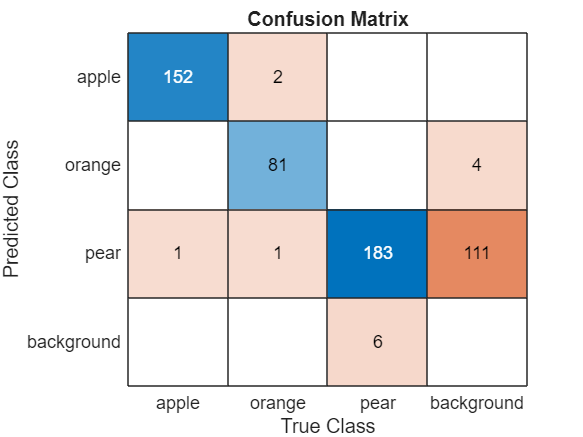

%confMat = utils.computeConfusionMatrixFromFolder(yolov8Det, splitFolder, classNames, scoreThreshold, iouThreshold, @calculateIoU);

allClassNames = [classNames(:); {'background'}];

utils.displayConfusionMatrix(confMat, allClassNames)

### Exercise: Extract TP, FP, FN of each class

function [TP, FP, FN] = extractConfusionMatrixValues(confusionMat)
    numClasses = size(confusionMat, 1);
    TP = zeros(numClasses, 1);
    FP = zeros(numClasses, 1);
    FN = zeros(numClasses, 1);
    for i = 1:numClasses
        TP(i) = confusionMat(i, i);
        FP(i) = sum(confusionMat(i, :)) - TP(i);
        FN(i) = sum(confusionMat(:, i)) - TP(i);
    end
end


[TP, FP, FN] = extractConfusionMatrixValues(confMat);


tableTP = table(string(allClassNames), TP, 'VariableNames', {'ClassName', 'True Positive'});
tableFP = table(string(allClassNames), FP, 'VariableNames', {'ClassName', 'False Positive'});
tableFN = table(string(allClassNames), FN, 'VariableNames', {'ClassName', 'False Negative'});

disp(tableTP)

     ClassName      True Positive
    ____________    _____________

    "apple"              152     
    "orange"              81     
    "pear"               183     
    "background"           0     



disp(tableFP)

     ClassName      False Positive
    ____________    ______________

    "apple"                2      
    "orange"               4      
    "pear"               113      
    "background"           6      



disp(tableFN)

     ClassName      False Negative
    ____________    ______________

    "apple"                1      
    "orange"               3      
    "pear"                 6      
    "background"         115      



### Precision

Measures the accuracy of the model in a class.  Proportion of true positives relative to the total number of assigned positives. Mathematically:


$$\textrm{Precision}=\frac{\textrm{TP}}{\textrm{TP}+\textrm{FP}}$$


Hay diferentes formas de calcular la precision, se puede calcular la precision de cada una de las clases, se puede calcular la precision total y una precision balanceada por clases.

Exercise. Crea una función para calcular la precision de cada clase y la precision total

Remember (/) divide matricialmente. (./) divide por elementos 

function precision = precisionFunc(TP, FP)
    
    denom = (TP + FP);

    precision = TP ./ denom;
    totalTP = sum(TP);
    total = totalTP + sum(FP);
    
    if total == 0
        total = NaN;
    end
    
    precisionMacro = sum(precision) / length(precision);
    totalPrecision =  totalTP / total;
    precision = [precision; precisionMacro];
    
end

precision = precisionFunc(TP, FP);
metricsClassNames = string([allClassNames(:); {'Overall'}]);
precisionTable = table(metricsClassNames, precision, 'VariableNames', {'ClassName', 'Precision'});
disp(precisionTable)

     ClassName      Precision
    ____________    _________

    "apple"          0.98701 
    "orange"         0.95294 
    "pear"           0.61824 
    "background"           0 
    "Overall"        0.63955 



### Recall

Measures the sensitivity of the model to detect a class. Ratio of true positives to the total number of actual positives. Mathematically:


$$\mathrm{Recall}=\frac{\mathrm{TP}}{\mathrm{TP}+\mathrm{FN}}$$


function recall = recallFunc(TP, FN)  
    recall = precisionFunc(TP, FN);
    
end

recall = recallFunc(TP, FN);

recallTable = table(metricsClassNames, recall, 'VariableNames', {'ClassName', 'Recall'});
disp(recallTable)

     ClassName      Recall 
    ____________    _______

    "apple"         0.99346
    "orange"        0.96429
    "pear"          0.96825
    "background"          0
    "Overall"        0.7315



### Precision/Recall Trade off

There is usually a trade-off between precision and recall, where better precision means lower recall and vice versa.

This is because precision measures not missing anything, while recall measures not leaving anything out.

### Precision-Recall curve

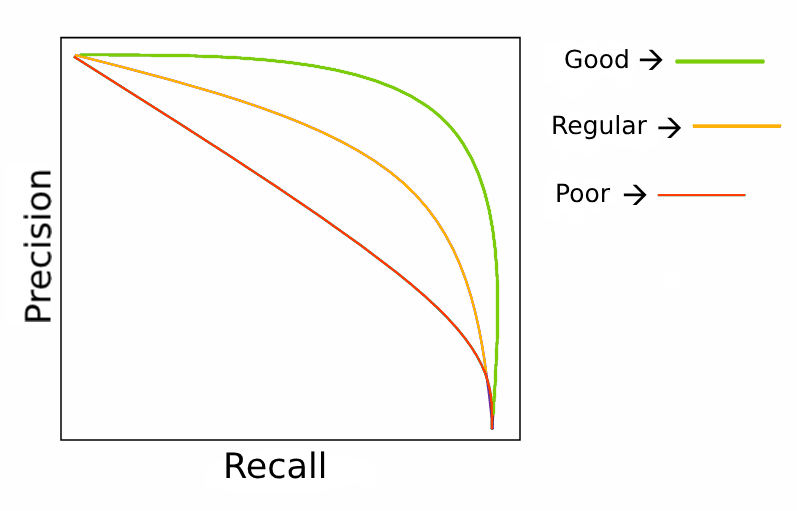

### Area Under Curve (AUC)

### Curva Receiver Operating Characteristic (ROC) 

### F1-score

F1-score is a metric that takes recall and precision into account in its value:


$${\mathrm{f1}}_{\mathrm{score}} =\frac{2\cdot \mathrm{presicion}\cdot \mathrm{recall}}{\mathrm{precision}+\mathrm{recall}}$$


### mAP@X

### Fitness

## All together

http://localhost:6006/

pyInterpreter = char(getPythonInterpreter());
logdir = fullfile(pwd)

logdir = 'C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision'

command = ['start "" "' pyInterpreter '" -m tensorboard.main --logdir "' logdir '"'];

disp(command) 

start "" "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision\win64\python\python" -m tensorboard.main --logdir "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\Lessons\from-code-to-robot\computer_vision"


system(command); 

disp('✅ TensorBoard is running in the background...');

✅ TensorBoard is running in the background...
